# Train DQN Agent to Swing Up and Balance Pendulum

This example shows how to train a deep Q-learning network (DQN) agent to swing up and balance a pendulum modeled in Simulink®.

For more information on DQN agents, see [Deep Q-Network Agents](docid:rl_ug#mw_101bb08b-96e7-439b-a628-afff98ca3b6f). For an example that trains a DQN agent in MATLAB®, see [MATLAB DQN Example](docid:rl_ug#mw_dce21438-174d-4cef-b95c-f4202e1324b5).

## Fix Random Seed Generator to Improve Reproducibility

The example code may involve computation of random numbers at various stages such as initialization of the agent, creation of the actor and critic, resetting the environment during simulations, generating observations (for stochastic environments), generating exploration actions, and sampling min-batches of experiences for learning. Fixing the random number stream preserves the sequence of the random numbers every time you run the code and improves reproducibility of results. You will fix the random number stream at various locations in the example.

Fix the random number stream with the seed `0` and random number algorithm Mersenne twister. For more information on random number generation see [`rng`](docid:matlab_ref#bsuymc2-1).

previousRngState = rng(0,"twister")

previousRngState = struct with fields:
     Type: 'twister'
     Seed: 0
    State: [625×1 uint32]


The output `previousRngState` is a structure that contains information about the previous state of the stream. You will restore the state at the end of the example. 

## Pendulum Swing-Up Model

The reinforcement learning environment for this example is a simple frictionless pendulum that initially hangs in a downward position. The training goal is to make the pendulum stand upright without falling over using minimal control effort.

Open the model.

mdl = "rlSimplePendulumModel";
open_system(mdl)

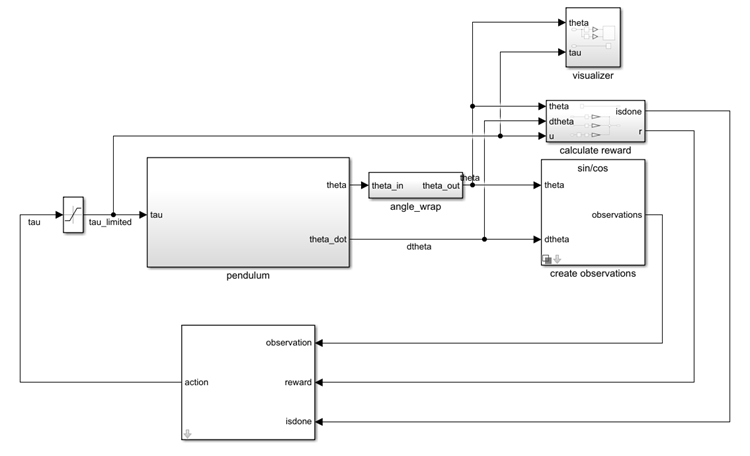

For this model:

- The upward balanced pendulum position is 0 radians, and the downward hanging position is `pi` radians.

- The torque action signal from the agent to the environment is from –2 to 2 N·m.

- The observations from the environment are the sine of the pendulum angle, the cosine of the pendulum angle, and the pendulum angle derivative.

- The reward $r_t$, provided at every time step, is


$$r_t =-\left({\theta_t }^2 +0\ldotp 1{\dot{\theta_t } }^2 +0\ldotp 001u_{t-1}^2 \right)$$


Here:

- $\theta_t$ is the angle of displacement from the upright position.

- $\dot{\theta_t }$ is the derivative of the displacement angle.

- $u_{t-1}$ is the control effort from the previous time step.

For more information on this model, see [Load Predefined Control System Environments](docid:rl_ug#mw_537f0c6d-2ccd-454b-95fa-3ee88ece74aa).

## Create Environment Object

Create a predefined environment interface for the pendulum.

env = rlPredefinedEnv("SimplePendulumModel-Discrete")

env = <a href=""matlab: help rl.env.SimulinkEnvWithAgent"">SimulinkEnvWithAgent</a> with properties:

           Model : rlSimplePendulumModel
      AgentBlock : rlSimplePendulumModel/RL Agent
        ResetFcn : []
  UseFastRestart : on


The interface has a discrete action space where the agent can apply one of three possible torque values to the pendulum: –2, 0, or 2 N·m.

To define the initial condition of the pendulum as hanging downward, specify an environment reset function using an anonymous function handle. This reset function sets the model workspace variable `theta0` to `pi`.

env.ResetFcn = @(in)setVariable(in,"theta0",pi,"Workspace",mdl);

Get the observation and action specification information from the environment.

obsInfo = getObservationInfo(env)

obsInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: "observations"
    Description: [0×0 string]
      Dimension: [3 1]
       DataType: "double"


actInfo = getActionInfo(env)

actInfo =   rlFiniteSetSpec with properties:

       Elements: [3×1 double]
           Name: "torque"
    Description: [0×0 string]
      Dimension: [1 1]
       DataType: "double"


Specify the simulation time `Tf` and the agent sample time `Ts` in seconds.

Ts = 0.05;
Tf = 20;

## Create DQN Agent

When you create the agent, the initial parameters of the critic network are initialized with random values. Fix the random number stream so that the agent is always initialized with the same parameter values. 

rng(0,"twister");

Create an agent initialization object to initialize the critic network with the hidden layer size 256.

initOpts = rlAgentInitializationOptions(NumHiddenUnit=256);

Specify the agent options for training using [`rlDQNAgentOptions`](docid:rl_ref#mw_d66ae7b0-1964-4f66-a2ee-cfc08fc3657e) and [`rlOptimizerOptions`](docid:rl_ref#mw_18a712bb-b821-4dd9-a7ad-460ad7f2aa03) objects. For this training:

- Specify the critic learning rate to be 5e-3. A large learning rate causes drastic updates which may lead to divergent behaviors, while a low value may require many updates before reaching the optimal point.

- Use a gradient threshold of 5 to clip the gradients. Clipping the gradients can improve training stability.

- Use mini-batches of 256 experiences. Smaller mini-batches are computationally efficient but may introduce variance in training. By contrast, larger batch sizes can make the training stable but require higher memory.

- Update the target critic network every 4 learning iterations with a smoothing factor of 5e-3.

- Do not use the double-DQN algorithm.

optimOpts = rlOptimizerOptions(LearnRate=5e-3, GradientThreshold=5);
agentOptions = rlDQNAgentOptions( ...
    SampleTime=Ts,...
    CriticOptimizerOptions=optimOpts,...
    ExperienceBufferLength=1e5,... 
    TargetSmoothFactor=5e-3,...
    UseDoubleDQN=false,...
    MiniBatchSize=256);

A DQN agent uses the epsilon-greedy algorithm the explore the action space during training. Specify a decay rate of 1e-3 for the epsilon value to gradually decay during training until the minimum value of 0.1 is reached. This promotes exploration towards the beginning when the agent does not have a good policy, and exploitation towards the end when the agent has learned the optimal policy.

agentOptions.EpsilonGreedyExploration.EpsilonDecay = 5e-5;
agentOptions.EpsilonGreedyExploration.EpsilonMin = 0.1;

Create the DQN agent using the observation and action input specifications, initialization options and agent options.

agent = rlDQNAgent(obsInfo,actInfo,initOpts,agentOptions);

For more information, see [`rlDQNAgent`](docid:rl_ref#mw_167d0061-c095-446e-828f-816916a0f227).

## Train Agent

To train the agent, first specify the training options. For this example, use the following options.

- Run each training for at most 1000 episodes, with each episode lasting at most 500 time steps.

- Display the training progress in the Reinforcement Learning Training Monitor dialog box (set the `Plots` option) and disable the command line display (set the `Verbose` option to `false`).

- Evaluate the performance of the greedy policy every 10 training episodes.

- Stop training when the agent receives an average cumulative reward greater than –1100 when evaluating the deterministic policy. At this point, the agent can quickly balance the pendulum in the upright position using minimal control effort.

- Save a copy of the agent for each episode where the cumulative reward is greater than –1100.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

% training options
trainingOptions = rlTrainingOptions(...
    MaxEpisodes=1000,...
    MaxStepsPerEpisode=500,...
    ScoreAveragingWindowLength=5,...
    Verbose=false,...
    Plots="training-progress",...
    StopTrainingCriteria="EvaluationStatistic",...
    StopTrainingValue=-1100,...
    SaveAgentCriteria="EvaluationStatistic",...
    SaveAgentValue=-1100);

% agent evaluator
evl = rlEvaluator(EvaluationFrequency=10, NumEpisodes=1);

Fix the random stream for reproducibility.

rng(0,"twister");

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training this agent is a computationally intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

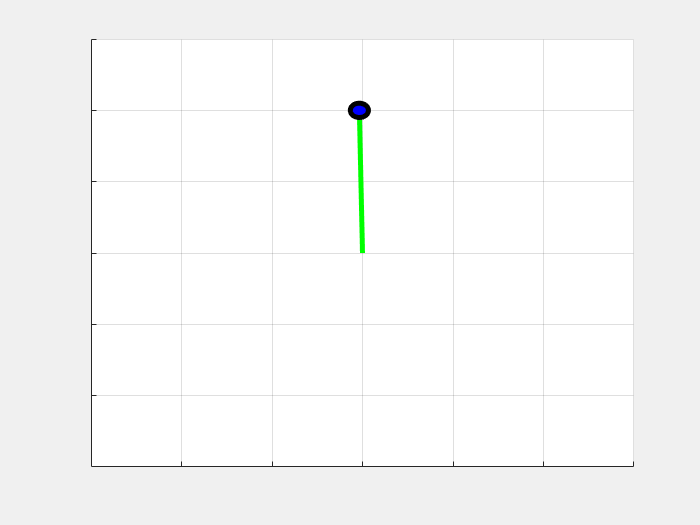

doTraining = true;
if doTraining
    % Train the agent.
    trainingStats = train(agent,env,trainingOptions, ...
        Evaluator=evl);
else
    % Load the pretrained agent for the example.
    load("SimulinkPendulumDQNMulti.mat","agent");
end

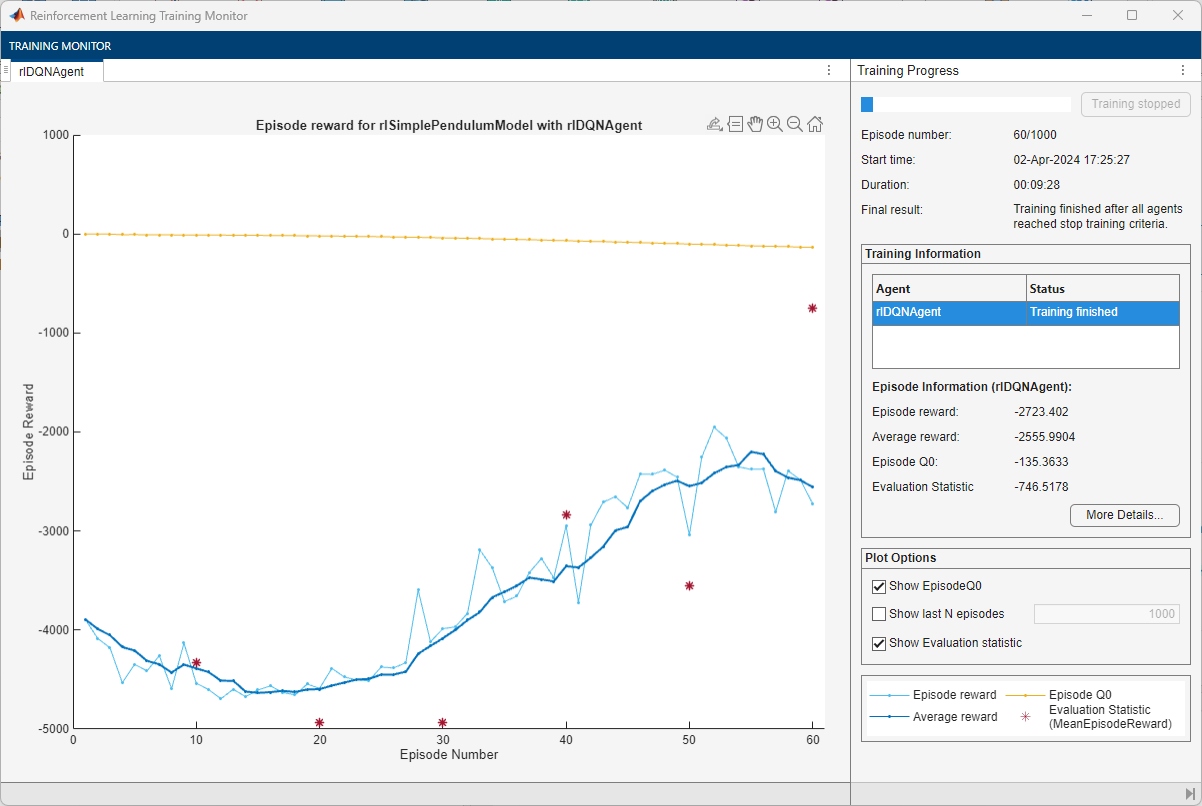

## Simulate DQN Agent

Fix the random stream for reproducibility.

rng(0,"twister");

To validate the performance of the trained agent, simulate it within the pendulum environment. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

simOptions = rlSimulationOptions(MaxSteps=500);
experience = sim(env,agent,simOptions);

Simulation aborted

Restore the random number stream using the information stored in `previousRngState`.

rng(previousRngState);

*Copyright 2019-2024 The MathWorks, Inc.*